## Задание 1. Синтез регулятора с заданной степенью устойчивости.

function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end

A=[3 5 4;
    -2 -4 -5;
    2 2 3];
B=[2;-1;1];

analyze_controllability(A, B);

Eigenvalues of A:
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =   -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 1.000000e+00i is controllable.


H =   -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 -1.000000e+00i is controllable.


H =    -5.0000   -5.0000   -4.0000    2.0000
    2.0000    2.0000    5.0000   -1.0000
   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 2

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


### Степень устойчивости 1

function [K] = syntK(A, B, a)
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        variable Y(size(B, 2), size(B, 1))
        P > 0.0001*eye(size(A, 1));
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
    cvx_end
    K = Y*inv(P);
end

K1 = syntK(A, B, 2)

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.7e+02|5.0e+01|1.3e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.857|1.5e+01|7.3e+00|1.1e+02| 0.000000e+00  2.541325e-03| 0:0:00| chol  1  1 
 2|0.882|0.717|1.8e+00|2.1e+00|3.1e+01| 0.000000e+00  2.025144e-03| 0:0:00| chol  1  1 
 3|0.940|0.949|1.1e-01|1.1e-01|1.6e+00| 0.000000e+00  2.370570e-04| 0:0:00| 

K1 =     3.3536    2.1216  -17.9071


function [K] = syntKmin(A, B, a, x0)
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        variable Y(size(B, 2), size(B, 1))
        variable mumu
        minimize mumu
        P > 0.0001*eye(size(A, 1));
        P*A'+A*P+2*a*P+Y'*B'+B*Y <= 0;
        [P x0;
         x0' 1] > 0;
        [P Y';
         Y mumu] > 0;
    cvx_end
    K = Y*inv(P);
end

K2 = syntKmin(A, B, 2, [0; 0; 0])

 
Calling SDPT3 4.0: 41 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
 dim. of free   var  =  9 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.8e+01|2.1e+02|6.7e+04| 9.997000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.940|0.930|5.9e+00|1.5e+01|1.1e+03| 8.518234e+00 -9.181422e+00| 0:0:00| chol  1  1 
 2|0.644|0.673|2.1e+00|4.9e+00|1.7e+02| 6.989065e+00 -1.746942e+01| 0:0:00| chol  1  1 
 3|0.934|0.9

K2 =    -0.1414   -0.1413   -7.8586


function [K] = syntRic(A, B, a, Q)
    syms P_ [size(A,1), size(A,1)]
    eqs = [A'*P_+P_*A-2*P_'*B*B'*P_+2*a*P_ + Q == 0];
    s = vpasolve(eqs, [P_], Random=true)
    P = [s.P_1_1 s.P_1_2;
        s.P_2_1 s.P_2_2];
    K = -B'*P;
end

function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

[AJ, BJ, P1] = j_stuff_B(A, B)

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



AJ =     -2     0     0
     0     2    -1
     0     1     2


BJ =          0
    0.7071
   -2.1213


P1 =    -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0


Aj = [2 -1;
    1 2];
Bj = BJ(2:3);

K3j = syntRic(Aj, Bj, 2, eye(2))

s = struct with fields:
    P_1_1: 65.744099163036165284961329785859
    P_2_1: 14.061352952424660577656837827633
    P_1_2: 14.061352952424660577656837827633
    P_2_2: 3.9695708407725603580397404108247


$$K3j = \left(\begin{array}{cc} -11.78002015288109177599540815148\,\sqrt{2} & -1.0763202150534897517688082975793\,\sqrt{2} \end{array}\right)$$

K3J = [0 K3j];
K3 = K3J/P1

$$K3 = \left(\begin{array}{ccc} 2.1526404301069795035376165951587 & 2.1526404301069795035376165951587 & -10.703699937827602024226599853901 \end{array}\right)$$

eig(A+B*K3)

$$ans = \left(\begin{array}{c} -2.0\\ -2.2755297538603112603444916293712+4.3744972279739704149981248731949\,\mathrm{i}\\ -2.2755297538603112603444916293712-4.3744972279739704149981248731949\,\mathrm{i} \end{array}\right)$$

K4j = syntRic(Aj, Bj, 2, zeros(2, 2))

s = struct with fields:
    P_1_1: 51.52
    P_2_1: 10.24
    P_1_2: 10.24
    P_2_2: 2.88


$$K4j = \left(\begin{array}{cc} -10.4\,\sqrt{2} & -0.8\,\sqrt{2} \end{array}\right)$$

K4J = [0 K4j];
K4 = K4J/P1

$$K4 = \left(\begin{array}{ccc} 1.6 & 1.6 & -9.6 \end{array}\right)$$

eig(A+B*K4)

$$ans = \left(\begin{array}{c} -2.0\\ -2.0+4.1231056256176605498214098559741\,\mathrm{i}\\ -2.0-4.1231056256176605498214098559741\,\mathrm{i} \end{array}\right)$$

eig(A+B*K1)

ans =   -4.6608 + 3.6560i
  -4.6608 - 3.6560i
  -2.0000 + 0.0000i


eig(A+B*K2)

ans =   -2.0000 + 2.8798i
  -2.0000 - 2.8798i
  -2.0000 + 0.0000i


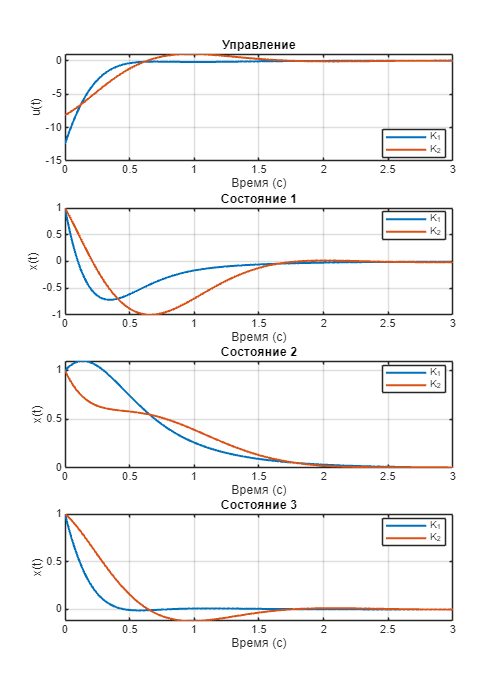

function simulate(A, B, K1, K2, x0, simtime, path)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'x0', x0);

    model_name = 'task1';
    load_system(model_name);

    % Simulink model name
    assignin('base', 'K', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;

    % Simulink model name
    assignin('base', 'K', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;


    % Plot state trajectories
    figure('Position', [0 0 500 700]);

    spn = 4;

    % Plot observer error
    subplot(spn, 1, 1);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время (с)');
    ylabel('u(t)');
    legend('K_1', 'K_2', 'Location', 'best');
    grid on;

    for idx=1:3
        subplot(spn, 1, idx+1);
        plot(t1, x1(:, idx), 'LineWidth', 1.5); hold on;
        plot(t2, x2(:, idx), 'LineWidth', 1.5);
        title(['Состояние ', int2str(idx)]);
        xlabel('Время (с)');
        ylabel('x(t)');
        legend('K_1', 'K_2', 'Location', 'best');
        grid on;
    end

    % Save the figure
    exportgraphics(gcf, ['figs/', path, '.png'], 'Resolution', 500);
end

x0 = [1; 1; 1];
simulate(A, B, K1, K2, x0, 3, 'task10');

### Степень устойчивости 2

K1 = syntK(A, B, 0.2)

 
Calling SDPT3 4.0: 15 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of free   var  =  3 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+02|4.8e+01|1.2e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.947|0.800|7.6e+00|9.7e+00|1.5e+02| 0.000000e+00  1.818259e-03| 0:0:00| chol  1  1 
 2|1.000|0.881|6.3e-05|1.2e+00|1.8e+01| 0.000000e+00  3.621549e-04| 0:0:00| chol  1  1 
 3|1.000|0.989|2.4e-05|1.4e-02|2.1e-01| 0.000000e+00  4.332033e-06| 0:0:00| 

K1 =    -1.6329   -2.3204   -9.5054


K2 = syntKmin(A, B, 0.2, [0; 0; 0])

 
Calling SDPT3 4.0: 41 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of sdp    var  = 14,   num. of sdp  blk  =  4
 dim. of free   var  =  9 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+01|1.6e+02|5.0e+04| 9.997000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.714|0.791|2.8e+01|3.4e+01|2.8e+03| 1.285574e+01 -1.391950e+01| 0:0:00| chol  1  1 
 2|0.483|0.885|1.4e+01|3.9e+00|5.4e+02| 1.775996e+01 -7.191190e+01| 0:0:00| chol  1  1 
 3|0.904|0.8

K2 =    -1.0712   -1.0712   -3.3288


eig(A+B*K1)

ans =    -1.4599
   -4.9909
   -2.0000


eig(A+B*K2)

ans =   -0.2000 + 2.0010i
  -0.2000 - 2.0010i
  -2.0000 + 0.0000i


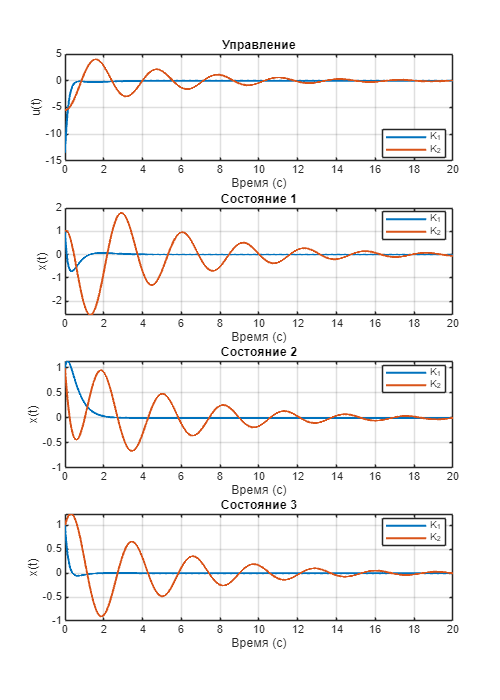

simulate(A, B, K1, K2, x0, 20, 'task11');